# Summarize or Pivot Data in Tables Using Groups

When working with data in tables, you can often organize the data into groups. You can group tabular data to summarize and interpret the data based on common characteristics. For example, if your data consists of events over a large time period, you can group the data by year to identify trends over time. The table variables that define the grouping criteria are considered the *grouping variables*, and the table variables that contain the values associated with each group are considered the *data variables*. This example shows how to create a grouped summary table or a pivoted table to inspect and compare groups of data using either the `groupsummary` or `pivot` function, respectively. This example also shows how to create a grouped summary table or a pivoted table using the Compute by Group or Pivot Table tasks in the Live Editor.

In this image, values in a data variable are grouped according to a grouping variable and then summarized using the mean. 

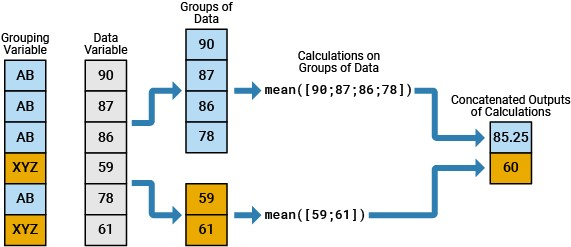

## Import Data as Table

Import the sample data set `outages.csv`. The file contains data for utility power outages in the United States, such as the affected region, the outage cause, and the number of affected customers. You can organize this data into groups using a single variable or using multiple variables.

T = readtable("outages.csv","TextType","string")

## Summarize Data Using One Grouping Variable

When you have one grouping variable, you can create a grouped summary table with rows that correspond to each unique group using the `groupsummary` function. The variables in the grouped summary table represent the statistics computed per group for the data variables. This type of summary is particularly useful for identifying patterns in the data and making comparisons between different groups.

In this image, a table with one grouping variable and two data variables is summarized, and the grouped summary table shows the group counts and the mean of each group within each data variable.

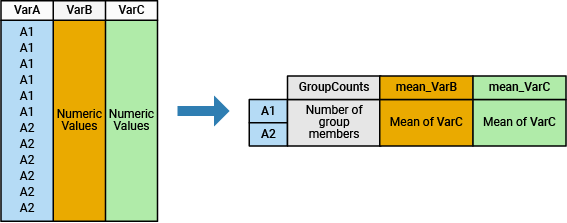

**Apply One Grouping Criterion**

Compute the total power loss for each outage cause. Specify the grouping variable as `Cause` and the data variable as `Loss`.

G1 = groupsummary(T,"Cause","sum","Loss")

Visualize the grouped summary table using a bar chart.

bar(G1.Cause,G1.sum_Loss)
title("Total Loss by Cause")

**Compute Multiple Statistics per Group**

Compute the mean and median power loss for each region. 

G2 = groupsummary(T,"Region",["mean" "median"],"Loss")

Visualize the grouped summary table using a bar chart. Each bar in a group of bars represents a different statistic. The statistics share a common scale because they represent the same data variable.

bar(G2.Region,[G2.mean_Loss G2.median_Loss])
legend("Mean Loss","Median Loss")
title("Loss by Region")

**Compute Statistic for Multiple Data Variables**

Compute the total power loss and total affected customers for each outage cause.

G3 = groupsummary(T,"Cause","sum",["Loss" "Customers"])

Visualize the grouped summary table using two bar charts. The statistics do not share a common scale because they represent different data variables.

ax = tiledlayout(1,2);
title(ax,"Total Loss and Customers by Cause")
nexttile
bar(G3.Cause,G3.sum_Loss)
ylabel("Total Power Loss")
nexttile
bar(G3.Cause,G3.sum_Customers,"magenta")
ylabel("Total Affected Customers")

Alternatively, to interactively summarize tabular data in a grouped summary table, use the [Compute by Group](docid:matlab_ref#mw_354e4ac3-6271-47e6-a886-135a6305ae62) Live Editor task. Live Editor Tasks are apps that you can embed in a live script to interactively explore parameters and options, immediately see the results, automatically generate the corresponding code.

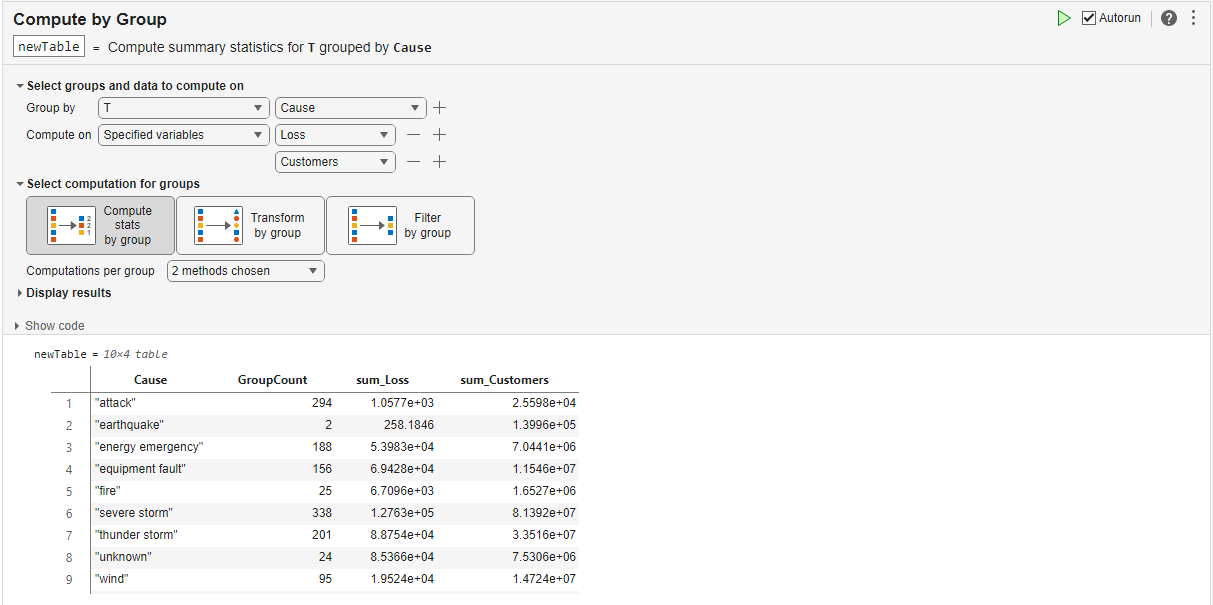

## Pivot and Summarize Data Using Multiple Grouping Variables

When you have more than one grouping variable, you can create a pivoted table with columns and rows that correspond to unique combinations of the values in the grouping variables using the `pivot` function. The data values in the pivoted table represent one statistic computed per group for one data variable. A pivoted table has more configuration options than a grouped summary table that you can create using `groupsummary`, and a pivoted table is useful for identifying relationships between groups. Alternatively, you can use the `groupsummary` function to apply more than one computation method or operate on more than one data variable.

In this image, a table with three grouping variables and one data variable is pivoted, and the pivoted table shows the sum of data values in each unique combination of groups.

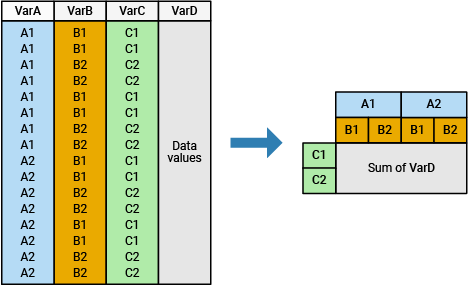

**Apply Two Grouping Criteria**

Compute the number of outages for each region per year. In this case, the two grouping variables are `Region` and `OutageTime`. One grouping variable designates the variables of the pivoted table, and one grouping variable designates the rows of the pivoted table. By default, the data values in the pivoted table are the group counts.

P1 = pivot(T,Rows="Region",Columns="OutageTime",ColumnsBinMethod="year",RowLabelPlacement="rownames")

Visualize the pivoted table using a heatmap.

xvar = P1.Properties.VariableNames;
yvar = P1.Properties.RowNames;
cvar = P1.Variables;

figure
heatmap(xvar,yvar,cvar)
title("Outage Count by Region and Year")
fig = gcf;
fig.Position(3) = fig.Position(3) * 2;

Alternatively, you can apply two grouping criteria using the `groupsummary` function, where groups are defined as unique combinations of the values in the `Region` and `OutageTime` grouping variables.

G4 = groupsummary(T,["Region" "OutageTime"],{"none" "year"},"sum",["Loss" "Customers"])

**Apply Three Grouping Criteria**

Compute the number of outages for each cause per region per number of customers. In this case, the three grouping variables are `Cause`, `Region`, and `Customers`. Define two bins for the `Customers` variable by specifying the `ColumnsBinMethod` name-value argument. Because multiple grouping variables designate the columns of the pivoted table, the pivoted table contains nested tables.

P2 = pivot(T,Rows="Cause",Columns=["Region" "Customers"],ColumnsBinMethod={"none",[0 100 Inf]},IncludeMissingGroups=false)

**Compute Marginal Totals**

You can display row-wise and column-wise statistics in a pivoted table using the `IncludeTotals` name-value argument. Compute the total power loss for each region per year, and include the marginal totals in the pivoted table. The last row of the pivoted table represents the total power loss for each year. The last variable of the pivoted table represents the total power loss for each region.

P3 = pivot(T,Rows="Region",Columns="OutageTime",ColumnsBinMethod="year",DataVariable="Loss",RowLabelPlacement="rownames",IncludeTotals=true)

Alternatively, to interactively summarize tabular data in a pivoted table and visualize the pivoted table in a different types of charts, use the [Pivot Table](docid:matlab_ref#mw_325bfa3b-b846-4bbe-8989-e4548ad51f79) Live Editor task.

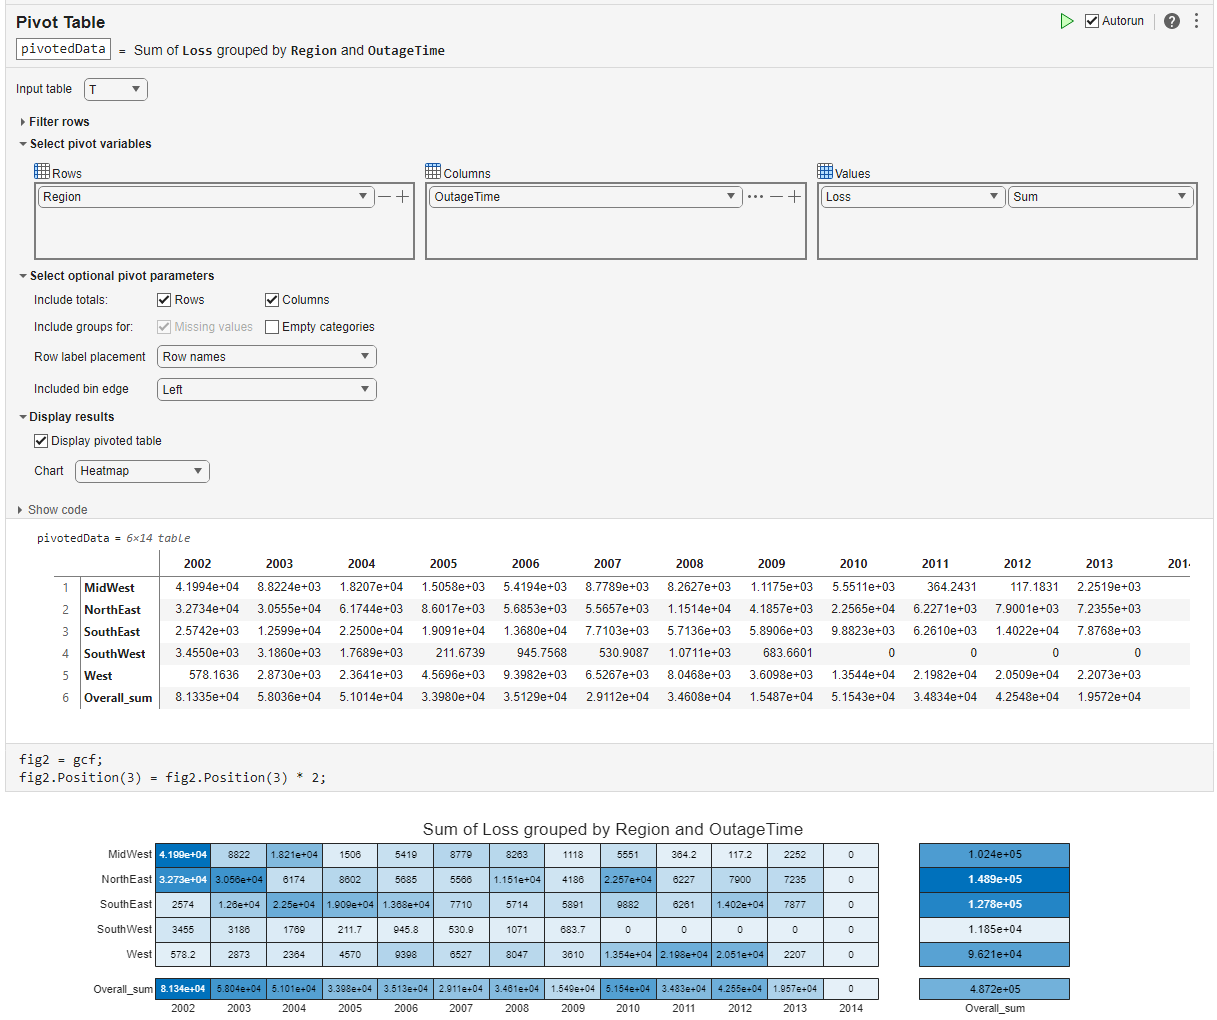

## Other Functions for Grouped Calculations

In most cases, `groupsummary` is the recommended function for identifying patterns in the data and making comparisons between one or more grouping variables. `pivot` is the recommended function for identifying relationships between multiple grouping variables or when you need additional configuration options.

To explore additional functions for grouped calculations, see the tips and recommendations in [Perform Calculations by Group in Table](docid:matlab_prog#buy5l07).

*Copyright 2024 The MathWorks, Inc.*